# Programmentwurf – Simulationstechnik (TSA24)

Elias Sehmsdorf (2369656)

Dominik Borowski (7373896)

In diesem Live Script werden die Aufgaben 1–5 des Programmentwurfs bearbeitet.

Ziel ist es, das nichtlineare Einspurmodell zu simulieren, ein lineares Modell abzuleiten und beide Ansätze zu vergleichen.


clear; clc; close all;


## Gemeinsame Parameter (aus Aufgabenstellung)


p.m  = 2000;                        % Masse [kg]
p.Jz = 4000;                        % Gierrträgheit [kg m^2]
p.lf = 1.43;                        % Abstand SP -> Vorderachse [m]
p.lr = 1.40;                        % Abstand SP -> Hinterachse [m]
p.cf = 70000;                       % Schräglaufsteifigkeit VA [N/rad]
p.cr = 140000;                      % Schräglaufsteifigkeit HA [N/rad]


Die Parameter beschreiben ein vereinfachtes Fahrzeugmodell mit linearem Reifenansatz (Schräglaufsteifigkeiten).

Alle Aufgaben nutzen dieselben Grundparameter, damit die Ergebnisse vergleichbar bleiben.

## Gemeinsame Simulationseinstellungen


tEnd = 6;                           % Simulationszeit [s]
x0   = [0; 0];                      % Anfangszustand: x=[beta; r] = [rad; rad/s]


Startbedingung: Fahrzeug fährt geradeaus (beta = 0) ohne Anfangs-Gierbewegung (r = 0).

tEnd begrenzt die Simulationsdauer, sodass das Einschwingverhalten gut sichtbar ist.

Da wir bei einer Geschwindigkeit von 18 [m/s] sind, ist eine Simulationslaufzeit von 6 Sekunden ausreichend, um die Stabilität zu erkennen und dennoch die vollständige Reaktion des Systems eindeutig wiederzuspiegeln.

## Fall aus Aufgabenstellung


v = 18;                             % Geschwindigkeit [m/s]
delta_deg = 5;                      % Lenkwinkelsprung [deg]
delta = deg2rad(delta_deg);         % [rad]

% Matrizen des linearen Modells fuer Simulink vorbereiten

A11 = (p.cf - p.cr) / (p.m * v);
A12 = (p.cr * p.lr - p.cf * p.lf) / (p.m * v^2) - 1;
A21 = (p.lf * p.cf + p.lr * p.cr) / p.Jz;
A22 = -(p.lf^2 * p.cf + p.lr^2 * p.cr) / (p.Jz * v);
A = [A11, A12; A21, A22];

B1 = p.cf / (p.m * v);
B2 = (p.lf * p.cf) / p.Jz;
B  = [B1; B2];


## Aufgabe 1 – Nichtlineares Modell in MATLAB (ODE45)

Ziel: Verlauf von beta und r für delta = 5°, v = 18 m/s (grafisch in ° und °/s)

Vorgehen: Das nichtlineare Differentialgleichungssystem wird mit ode45 numerisch integriert.

Anschließend werden Schwimmwinkel beta und Giergeschwindigkeit r in Grad bzw. Grad/s dargestellt.


fprintf('Aufgabe 1');

Aufgabe 1

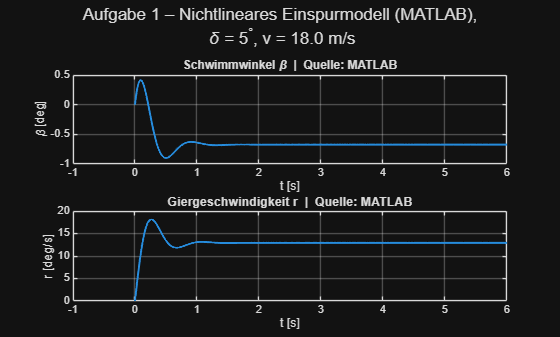


odefun = @(t,x) bicycle_nonlinear_ode_A1(t, x, delta, v, p);
opts = odeset('RelTol',1e-8,'AbsTol',1e-10);

[t1, x1] = ode45(odefun, [0 tEnd], x0, opts);

beta1_deg = rad2deg(x1(:,1));
r1_deg_s  = rad2deg(x1(:,2));

figure('Name','Aufgabe 1: Nichtlineares Einspurmodell (MATLAB)');
plot_beta_r_A1(t1, beta1_deg, r1_deg_s, ...
    sprintf('Aufgabe 1 – Nichtlineares Einspurmodell (MATLAB),\n \\delta = %.0f^\\circ, v = %.1f m/s', delta_deg, v), ...
    'MATLAB');


% Funktionen zu Aufgabe 1

function dx = bicycle_nonlinear_ode_A1(~, x, delta, v, p)
    beta = x(1);                    % [rad]
    r    = x(2);                    % [rad/s]
    cb = cos(beta);

    alpha_f = delta - (p.lf * r) / (v * cb) + tan(beta);
    alpha_r = (p.lr * r) / (v * cb) - tan(beta);

    Fy_f = p.cf * alpha_f;
    Fy_r = p.cr * alpha_r;

    beta_dot = -r + (1/(p.m * v)) * ((Fy_f * cos(delta) / cb) + (Fy_r / cb));
    r_dot    = (1/p.Jz) * (p.lf * Fy_f * cos(delta) - p.lr * Fy_r);

    dx = [beta_dot; r_dot];
end

function plot_beta_r_A1(t, beta_deg, r_deg_s, mainTitle, sourceLabel)
    sgtitle(mainTitle);
    tEndPlot = max(t);

    subplot(2,1,1)
    plot(t, beta_deg, 'LineWidth', 1.5);
    grid on;
    xlim([-1 tEndPlot])
    xlabel('t [s]');
    ylabel('\beta [deg]');
    title(['Schwimmwinkel \beta  |  Quelle: ' sourceLabel]);

    subplot(2,1,2)
    plot(t, r_deg_s, 'LineWidth', 1.5);
    grid on;
    xlim([-1 tEndPlot])
    xlabel('t [s]');
    ylabel('r [deg/s]');
    title(['Giergeschwindigkeit r  |  Quelle: ' sourceLabel]);
end


## Aufgabe 2 – Nichtlineares Modell in Simulink

Ziel: gleiche Rechnung wie Aufgabe 1, aber Modell in Simulink

In Simulink wird dasselbe nichtlineare Modell als Blockschaltbild umgesetzt und simuliert.

Die Ausgabe erfolgt über To Workspace und wird anschließend identisch wie in Aufgabe 1 geplottet.


fprintf('Aufgabe 2');

Aufgabe 2

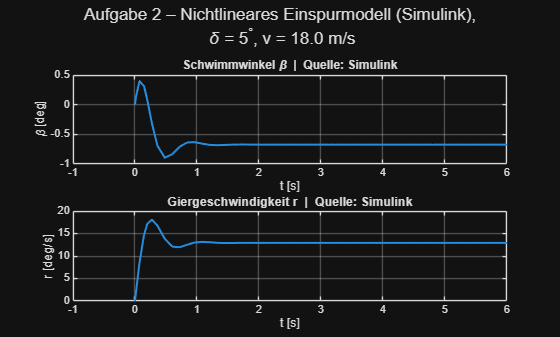


delta_sim = deg2rad(5);

assignin('base','A',A);
assignin('base','B',B);
assignin('base','p',p);
assignin('base','v',v);
assignin('base','delta_sim',delta_sim);

out2 = sim("Simulink.slx");

t2 = out2.beta_nonlinear.Time;
beta2_deg = out2.beta_nonlinear.Data;
r2_deg_s  = out2.dpsi_nonlinear.Data;

figure('Name','Aufgabe 2: Nichtlineares Einspurmodell (Simulink)');
plot_beta_r_A2(t2, beta2_deg, r2_deg_s, ...
    sprintf('Aufgabe 2 – Nichtlineares Einspurmodell (Simulink),\n \\delta = %.0f^\\circ, v = %.1f m/s', delta_deg, v), ...
    'Simulink');


% Funktionen zu Aufgabe 2

function plot_beta_r_A2(t, beta_deg, r_deg_s, mainTitle, sourceLabel)
    sgtitle(mainTitle);
    tEndPlot = max(t);

    subplot(2,1,1)
    plot(t, beta_deg, 'LineWidth', 1.5);
    grid on;
    xlim([-1 tEndPlot])
    xlabel('t [s]');
    ylabel('\beta [deg]');
    title(['Schwimmwinkel \beta  |  Quelle: ' sourceLabel]);

    subplot(2,1,2)
    plot(t, r_deg_s, 'LineWidth', 1.5);
    grid on;
    xlim([-1 tEndPlot])
    xlabel('t [s]');
    ylabel('r [deg/s]');
    title(['Giergeschwindigkeit r  |  Quelle: ' sourceLabel]);
end


## Aufgabe 3 – Linearisierung, Vergleich linear vs. nichtlinear (MATLAB)

Vergleich für delta = 5° und delta = 20°, grafisch + max. Abweichung ausgeben

Das linearisierte Zustandsraummodell wird um den Betriebspunkt (beta=0, r=0, delta=0) gebildet.

Danach werden lineares und nichtlineares Modell für kleine (5°) und größere (20°) Lenkwinkel verglichen.


fprintf('Aufgabe 3\n');

Aufgabe 3



% Systemmatrizen für den Betriebspunkt (delta=0, beta=0, r=0)

A11 = (p.cf - p.cr) / (p.m * v);
A12 = (p.cr * p.lr - p.cf * p.lf) / (p.m * v^2) - 1;
A21 = (p.lf * p.cf + p.lr * p.cr) / p.Jz;
A22 = -(p.lf^2 * p.cf + p.lr^2 * p.cr) / (p.Jz * v);
A = [A11, A12; A21, A22];

B1 = p.cf / (p.m * v);
B2 = (p.lf * p.cf) / p.Jz;
B = [B1; B2];

sys_lin = ss(A, B, eye(2), [0; 0]);

t_sim = linspace(0, tEnd, 1000);


## Vergleich für delta = 5°


delta5 = deg2rad(5);
u5 = delta5 * ones(size(t_sim));

% Lineare Simulation

y_lin_5 = lsim(sys_lin, u5, t_sim, x0);
beta_lin_5 = y_lin_5(:,1);          % [rad]
r_lin_5    = y_lin_5(:,2);          % [rad/s]

% Nichtlineare Simulation

odefun_5 = @(t,x) bicycle_nonlinear_ode_A1(t, x, delta5, v, p);
[~, x_nl_5] = ode45(odefun_5, t_sim, x0);
beta_nl_5 = x_nl_5(:,1);            % [rad]
r_nl_5    = x_nl_5(:,2);            % [rad/s]


## Vergleich für delta = 20°


delta20 = deg2rad(20);
u20 = delta20 * ones(size(t_sim));

% Lineare Simulation

y_lin_20 = lsim(sys_lin, u20, t_sim, x0);
beta_lin_20 = y_lin_20(:,1);        % [rad]
r_lin_20    = y_lin_20(:,2);        % [rad/s]

% Nichtlineare Simulation

odefun_20 = @(t,x) bicycle_nonlinear_ode_A1(t, x, delta20, v, p);
[~, x_nl_20] = ode45(odefun_20, t_sim, x0);
beta_nl_20 = x_nl_20(:,1);          % [rad]
r_nl_20    = x_nl_20(:,2);          % [rad/s]


## Auswertung: maximale Abweichungen


max_err_beta_5  = max(abs(beta_nl_5 - beta_lin_5));
max_err_r_5     = max(abs(r_nl_5    - r_lin_5));
max_err_beta_20 = max(abs(beta_nl_20 - beta_lin_20));
max_err_r_20    = max(abs(r_nl_20    - r_lin_20));

fprintf('--- MATLAB Vergleich ---\n');

--- MATLAB Vergleich ---


fprintf('--- Abweichungen bei 5° ---\n');

--- Abweichungen bei 5° ---


fprintf('Schwimmwinkel:       %.4f°\n', rad2deg(max_err_beta_5));

Schwimmwinkel:       0.0034°


fprintf('Giergeschwindigkeit: %.4f°/s\n\n', rad2deg(max_err_r_5));

Giergeschwindigkeit: 0.0572°/s




fprintf('--- Abweichungen bei 20° ---\n');

--- Abweichungen bei 20° ---


fprintf('Schwimmwinkel:       %.4f°\n', rad2deg(max_err_beta_20));

Schwimmwinkel:       0.1955°


fprintf('Giergeschwindigkeit: %.4f°/s\n\n', rad2deg(max_err_r_20));

Giergeschwindigkeit: 3.6402°/s



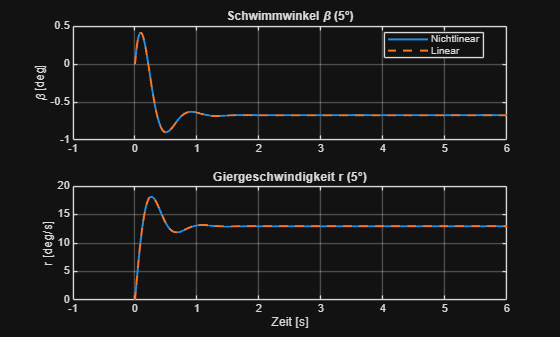


% Plot für 5 Grad

figure('Name', 'Aufgabe 3 (MATLAB): Vergleich bei 5°');
subplot(2,1,1);
plot(t_sim, rad2deg(beta_nl_5), 'LineWidth', 1.5); hold on;
plot(t_sim, rad2deg(beta_lin_5), '--', 'LineWidth', 1.5);
grid on; xlim([-1 max(t_sim)]);
ylabel('\beta [deg]'); title('Schwimmwinkel \beta (5°)');
legend('Nichtlinear', 'Linear', 'Location', 'best');

subplot(2,1,2);
plot(t_sim, rad2deg(r_nl_5), 'LineWidth', 1.5); hold on;
plot(t_sim, rad2deg(r_lin_5), '--', 'LineWidth', 1.5);
grid on; xlim([-1 max(t_sim)]);
xlabel('Zeit [s]'); ylabel('r [deg/s]'); title('Giergeschwindigkeit r (5°)');

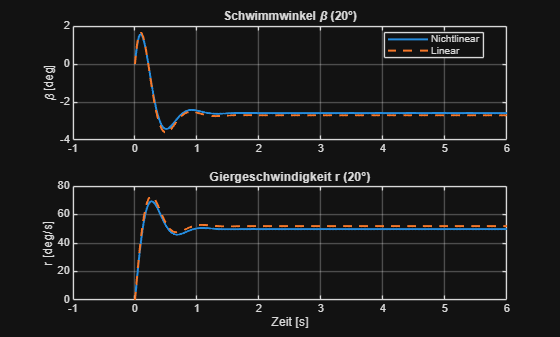


% Plot für 20 Grad

figure('Name', 'Aufgabe 3 (MATLAB): Vergleich bei 20°');
subplot(2,1,1);
plot(t_sim, rad2deg(beta_nl_20), 'LineWidth', 1.5); hold on;
plot(t_sim, rad2deg(beta_lin_20), '--', 'LineWidth', 1.5);
grid on; xlim([-1 max(t_sim)]);
ylabel('\beta [deg]'); title('Schwimmwinkel \beta (20°)');
legend('Nichtlinear', 'Linear', 'Location', 'best');

subplot(2,1,2);
plot(t_sim, rad2deg(r_nl_20), 'LineWidth', 1.5); hold on;
plot(t_sim, rad2deg(r_lin_20), '--', 'LineWidth', 1.5);
grid on; xlim([-1 max(t_sim)]);
xlabel('Zeit [s]'); ylabel('r [deg/s]'); title('Giergeschwindigkeit r (20°)');

## Aufgabe 3 – Vergleich linear vs. nichtlinear (Simulink)

Hier wird das gleiche nichtlineare und lineare Modell in einer Simulink-Datei simuliert.

Die maximale Abweichung wird robust in MATLAB aus den geloggten Timeseries berechnet.


modellName = "Simulink.slx";

% 5 Grad

delta_sim = deg2rad(5);

assignin('base','A',A);
assignin('base','B',B);
assignin('base','p',p);
assignin('base','v',v);
assignin('base','delta_sim',delta_sim);

out_5 = sim(modellName);

err_beta_5 = max(abs(out_5.beta_nonlinear.Data - out_5.beta_linear.Data));
err_dpsi_5 = max(abs(out_5.dpsi_nonlinear.Data - out_5.dpsi_linear.Data));

fprintf('--- SIMULINK Vergleich ---\n');

--- SIMULINK Vergleich ---


fprintf('--- Ergebnisse bei 5° Lenkwinkelsprung ---\n');

--- Ergebnisse bei 5° Lenkwinkelsprung ---


fprintf('Max. Abweichung Schwimmwinkel:       %.4f°\n', err_beta_5);

Max. Abweichung Schwimmwinkel:       0.0030°


fprintf('Max. Abweichung Giergeschwindigkeit: %.4f°/s\n\n', err_dpsi_5);

Max. Abweichung Giergeschwindigkeit: 0.0567°/s



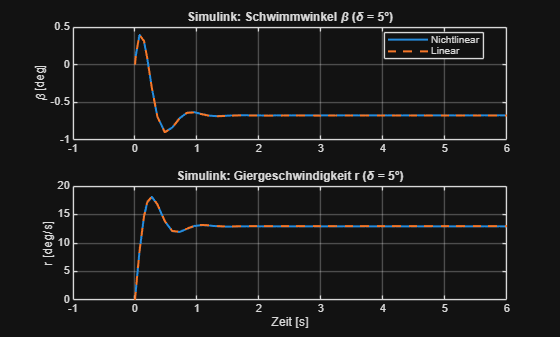


figure('Name', 'Aufgabe 3 (Simulink): Vergleich bei 5°');
subplot(2,1,1);
plot(out_5.beta_nonlinear.Time, out_5.beta_nonlinear.Data, 'LineWidth', 1.5); hold on;
plot(out_5.beta_linear.Time,    out_5.beta_linear.Data,    '--', 'LineWidth', 1.5);
grid on; xlim([-1 max(out_5.beta_nonlinear.Time)]);
ylabel('\beta [deg]');
title('Simulink: Schwimmwinkel \beta (\delta = 5°)');
legend('Nichtlinear', 'Linear', 'Location', 'best');

subplot(2,1,2);
plot(out_5.dpsi_nonlinear.Time, out_5.dpsi_nonlinear.Data, 'LineWidth', 1.5); hold on;
plot(out_5.dpsi_linear.Time,    out_5.dpsi_linear.Data,    '--', 'LineWidth', 1.5);
grid on; xlim([-1 max(out_5.dpsi_nonlinear.Time)]);
xlabel('Zeit [s]');
ylabel('r [deg/s]');
title('Simulink: Giergeschwindigkeit r (\delta = 5°)');


% 20 Grad

delta_sim = deg2rad(20);

assignin('base','A',A);
assignin('base','B',B);
assignin('base','p',p);
assignin('base','v',v);
assignin('base','delta_sim',delta_sim);

out_20 = sim(modellName);

err_beta_20 = max(abs(out_20.beta_nonlinear.Data - out_20.beta_linear.Data));
err_dpsi_20 = max(abs(out_20.dpsi_nonlinear.Data - out_20.dpsi_linear.Data));

fprintf('--- Ergebnisse bei 20° Lenkwinkelsprung ---\n');

--- Ergebnisse bei 20° Lenkwinkelsprung ---


fprintf('Max. Abweichung Schwimmwinkel:       %.4f°\n', err_beta_20);

Max. Abweichung Schwimmwinkel:       0.1901°


fprintf('Max. Abweichung Giergeschwindigkeit: %.4f°/s\n\n', err_dpsi_20);

Max. Abweichung Giergeschwindigkeit: 3.6274°/s



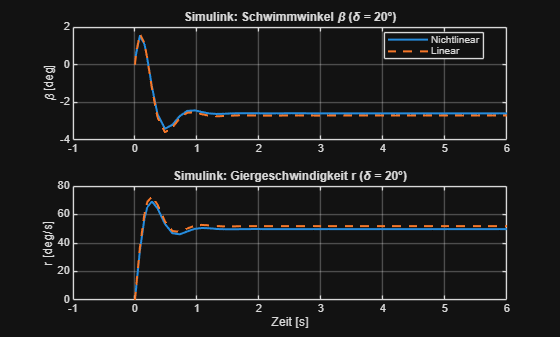


figure('Name', 'Aufgabe 3 (Simulink): Vergleich bei 20°');
subplot(2,1,1);
plot(out_20.beta_nonlinear.Time, out_20.beta_nonlinear.Data, 'LineWidth', 1.5); hold on;
plot(out_20.beta_linear.Time,    out_20.beta_linear.Data,    '--', 'LineWidth', 1.5);
grid on; xlim([-1 max(out_20.beta_nonlinear.Time)]);
ylabel('\beta [deg]');
title('Simulink: Schwimmwinkel \beta (\delta = 20°)');
legend('Nichtlinear', 'Linear', 'Location', 'best');

subplot(2,1,2);
plot(out_20.dpsi_nonlinear.Time, out_20.dpsi_nonlinear.Data, 'LineWidth', 1.5); hold on;
plot(out_20.dpsi_linear.Time,    out_20.dpsi_linear.Data,    '--', 'LineWidth', 1.5);
grid on; xlim([-1 max(out_20.dpsi_nonlinear.Time)]);
xlabel('Zeit [s]');
ylabel('r [deg/s]');
title('Simulink: Giergeschwindigkeit r (\delta = 20°)');

## Aufgabe 4 – Bode-Diagramm (linearisiertes Modell, Ausgang beta)

Das Bode-Diagramm beschreibt das Frequenzverhalten der linearen Übertragungsstrecke von Lenkwinkel delta zu Schwimmwinkel beta.

Der vorgegebene Frequenzbereich ist in Hz angegeben, für bode() wird er in rad/s umgerechnet.


fprintf('Aufgabe 4');

Aufgabe 4

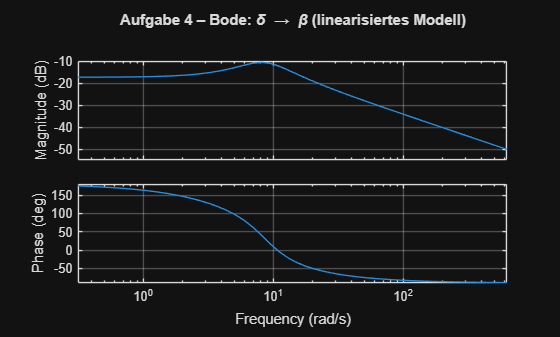


sys_beta = sys_lin(1);

f_Hz_start = 0.05;
f_Hz_end   = 100;

w_start = 2*pi*f_Hz_start;
w_end   = 2*pi*f_Hz_end;

figure('Name','Aufgabe 4: Bode – delta -> beta (linear)');
bode(sys_beta, {w_start, w_end});
grid on;
title('Aufgabe 4 – Bode: \delta \rightarrow \beta (linearisiertes Modell)');

## Aufgabe 5 – Optimierung: Geschwindigkeit v, sodass beta(Ende) möglichst klein ist

Ziel: Es wird die Geschwindigkeit v gesucht, bei der der Endwert |beta(tEnd)| minimal wird (delta = 5°).

Dazu wird fminbnd verwendet, welches die Kostenfunktion im Bereich [v_min, v_max] iterativ minimiert.


fprintf('Aufgabe 5');

Aufgabe 5


delta_opt = deg2rad(5);

v_min = 1;
v_max = 60;

opt_fun = @(v_test) cost_beta_end_linear_A5(v_test, p, delta_opt, x0, tEnd);

options = optimset('TolX',1e-2, 'Display','iter');
[v_opt, cost_opt] = fminbnd(opt_fun, v_min, v_max, options);

 
 Func-count     x          f(x)         Procedure
    1         23.536      1.09573        initial
    2         37.464      1.45526        golden
    3         14.928     0.217847        golden
    4        9.60798      1.83302        golden
    5         18.216      0.69939        golden
    6        12.8959     0.278564        golden
    7        14.3627     0.100455        parabolic
    8        14.0042    0.0186063        parabolic
    9        13.5809    0.0864342        golden
   10        13.9538   0.00657886        parabolic
   11        13.8675    0.0142771        parabolic
   12        13.9293  0.000693987        parabolic
   13         13.919   0.00178036        parabolic
   14        13.9326    0.0014966        parabolic
   15        13.9259  0.000109199        parabolic
   16        13.9226  0.000912956        golden
 
Optimization terminated:
 the current x satisfies the termination criteria using OPTIONS.TolX of 1.000000e-02 




fprintf('Aufgabe 5 – Optimierung (linear)\n');

Aufgabe 5 – Optimierung (linear)


fprintf('Optimales v: %.2f m/s (%.1f km/h)\n', v_opt, v_opt*3.6);

Optimales v: 13.93 m/s (50.1 km/h)


fprintf('|beta(tEnd)|: %.6f deg\n\n', cost_opt);

|beta(tEnd)|: 0.000109 deg



Interpretation:

Die Optimierung liefert eine Geschwindigkeit, bei der das linearisierte Modell am Ende der Simulation nahezu keinen Schwimmwinkel mehr aufweist.

Physikalisch bedeutet das: Für diese v kompensieren sich die dynamischen Anteile des Systems so, dass beta bis tEnd weitgehend ausklingt.

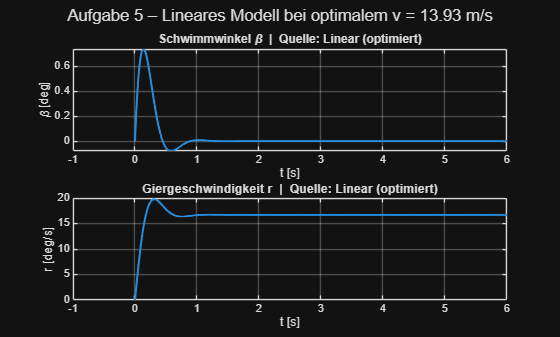


[ts_opt, beta_opt_deg, r_opt_deg_s] = simulate_linear_step_A5(v_opt, p, delta_opt, x0, tEnd);

figure('Name','Aufgabe 5: Ergebnis bei optimalem v (linear)');
plot_beta_r_A5(ts_opt, beta_opt_deg, r_opt_deg_s, ...
    sprintf('Aufgabe 5 – Lineares Modell bei optimalem v = %.2f m/s', v_opt), ...
    'Linear (optimiert)');



% Funktionen zu Aufgabe 5

function cost_deg = cost_beta_end_linear_A5(v_test, p, delta_step, x0, tEnd)
    if v_test <= 0
        cost_deg = inf;
        return;
    end

    A11 = (p.cf - p.cr) / (p.m * v_test);
    A12 = (p.cr * p.lr - p.cf * p.lf) / (p.m * v_test^2) - 1;
    A21 = (p.lf * p.cf + p.lr * p.cr) / p.Jz;
    A22 = -(p.lf^2 * p.cf + p.lr^2 * p.cr) / (p.Jz * v_test);
    A = [A11, A12; A21, A22];

    B1 = p.cf / (p.m * v_test);
    B2 = (p.lf * p.cf) / p.Jz;
    B = [B1; B2];

    sys = ss(A, B, eye(2), [0;0]);

    t = linspace(0, tEnd, 800);
    u = delta_step * ones(size(t));

    y = lsim(sys, u, t, x0);
    beta_end = y(end,1);            % [rad]

    cost_deg = abs(rad2deg(beta_end));
end

function [t, beta_deg, r_deg_s] = simulate_linear_step_A5(v, p, delta_step, x0, tEnd)
    A11 = (p.cf - p.cr) / (p.m * v);
    A12 = (p.cr * p.lr - p.cf * p.lf) / (p.m * v^2) - 1;
    A21 = (p.lf * p.cf + p.lr * p.cr) / p.Jz;
    A22 = -(p.lf^2 * p.cf + p.lr^2 * p.cr) / (p.Jz * v);
    A = [A11, A12; A21, A22];

    B1 = p.cf / (p.m * v);
    B2 = (p.lf * p.cf) / p.Jz;
    B = [B1; B2];

    sys = ss(A, B, eye(2), [0;0]);

    t = linspace(0, tEnd, 800);
    u = delta_step * ones(size(t));
    y = lsim(sys, u, t, x0);

    beta_deg = rad2deg(y(:,1));
    r_deg_s  = rad2deg(y(:,2));
end

function plot_beta_r_A5(t, beta_deg, r_deg_s, mainTitle, sourceLabel)
    sgtitle(mainTitle);
    tEndPlot = max(t);

    subplot(2,1,1)
    plot(t, beta_deg, 'LineWidth', 1.5);
    grid on;
    xlim([-1 tEndPlot])
    xlabel('t [s]');
    ylabel('\beta [deg]');
    title(['Schwimmwinkel \beta  |  Quelle: ' sourceLabel]);

    subplot(2,1,2)
    plot(t, r_deg_s, 'LineWidth', 1.5);
    grid on;
    xlim([-1 tEndPlot])
    xlabel('t [s]');
    ylabel('r [deg/s]');
    title(['Giergeschwindigkeit r  |  Quelle: ' sourceLabel]);
end
